# Cavity flow with Physics-Informed Neural Networks

Solve cavity flow governed by 2d steady Navier-Stokes equations and continuity equation, using a Physics-Informed Neural Network (PINN).

The 2d, steady Navier-Stokes equations for an incompressible fluid are:


$$\frac{\partial u}{\partial x} + \frac{\partial v}{\partial y} = 0 
$$



$$u\frac{\partial u}{\partial x} + v\frac{\partial u}{\partial y} + \frac{\partial p}{\partial x} - \frac{1}{Re}\bigg( \frac{\partial^2 u}{\partial x^2} + \frac{\partial^2 u}{\partial y^2} \bigg) = 0$$



$$u\frac{\partial v}{\partial x} + v\frac{\partial v}{\partial y} + \frac{\partial p}{\partial y} - \frac{1}{Re}\bigg( \frac{\partial^2 v}{\partial x^2} + \frac{\partial^2 v}{\partial y^2} \bigg) = 0$$


`(x,y)` are the spatial coordinates, `(u,v)` is the fluid velocity, `p` is the pressure, `Re` is the Reynolds number.

In order to automatically satisfy the continuity equation we use the stream function psi such that `u=psi_y` and `v=-psi_x`. The boundary conditions are `(u,v)=(1,0)` and the top boundary and `(u,v)=(0,0)` at the other boundaries. The Reynolds number `Re=100`.

The PINNs model takes the spatial coordinates `(x,y)` as inputs and returns the streamfunction and pressure `(psi,p)` as outputs.

## Set parameters.

Re = 100;
u0 = 1;

## Create network

% Create basic MLP network architecture with two inputs (x,y) and two
% outputs (psi,p).
numHiddenUnits = 32;
net = dlnetwork();
layers = [ featureInputLayer(1, Name="x")
    concatenationLayer(1, 2)
    fullyConnectedLayer(numHiddenUnits)
    swishLayer()
    fullyConnectedLayer(numHiddenUnits)
    swishLayer()
    fullyConnectedLayer(numHiddenUnits)
    swishLayer() 
    fullyConnectedLayer(numHiddenUnits)
    swishLayer(Name="swishout")
    fullyConnectedLayer(1, Name="psiFree") ];
net = addLayers(net, layers);
net = addLayers(net, fullyConnectedLayer(1, Name="p"));
net = connectLayers(net, "swishout", "p");
net = addInputLayer(net, featureInputLayer(1, Name="y"), Initialize=false);

% Add anchor functions to strictly enforce boundary conditions on the
% streamfunction.
net = addLayers(net, [functionLayer(@(x)4.*x.*(1-x), Name="anchorX", Acceleratable=true); multiplicationLayer(3, Name="psi")]);
net = addLayers(net, functionLayer(@(y)4.*y.*(1-y), Name="anchorY", Acceleratable=true));
net = connectLayers(net, "x", "anchorX");
net = connectLayers(net, "y", "anchorY");
net = connectLayers(net, "anchorY", "psi/in2");
net = connectLayers(net, "psiFree", "psi/in3");

% Make sure outputs are ordered (psi,p).
net.OutputNames = ["psi", "p"];

% Initialize the network and cast to double precision.
net = initialize(net);
net = dlupdate(@double, net);

## Create training input

numTrainSamples = 1e4;
xyEquation = rand([numTrainSamples 2]);

numBoundarySamples = floor(numTrainSamples/2);
xyTopBottom = rand([numBoundarySamples 2]); % top-bottom boundaries.
xyTopBottom(:, 2) = round(xyTopBottom(:, 2)); % y-position is 0 or 1.

xyLeftRight = rand([numBoundarySamples 2]); % left-right boundaries.
xyLeftRight(:, 1) = round(xyLeftRight(:, 1)); % x-position is 0 or 1.

xyBoundary = cat(1, xyTopBottom, xyLeftRight);
idxPerm = randperm(size(xyBoundary, 1));
xyBoundary = xyBoundary(idxPerm, :);

## Create training output

zeroVector = zeros([numTrainSamples 1]);
uvBoundary = [zeroVector zeroVector];
uvBoundary(:, 1) = u0.*floor( xyBoundary(:, 2) );

## Train the model

% Prepare training data.
xyEquation = dlarray(xyEquation);
xyBoundary = dlarray(xyBoundary);
if canUseGPU
    xyEquation = gpuArray(xyEquation);
    xyBoundary = gpuArray(xyBoundary);
end

% Create checkpointing directory.
checkpointFrequency = 1e3;
checkpointDirName = "checkpoints";
if ~exist(checkpointDirName, "dir")
    mkdir(checkpointDirName)
end

% Train with L-BFGS.
maxEpochs = 1e4;
solverState = [];
lossFcn = dlaccelerate(@pinnsLossFunction);
lbfgsLossFcn = @(n)dlfeval(lossFcn, n, xyEquation, xyBoundary, zeroVector, uvBoundary, Re);
totalTime = 0;
printFrequency = 1e3;
for epoch = 1:maxEpochs
    tic;
    [net, solverState] = lbfgsupdate(net, lbfgsLossFcn, solverState, NumLossFunctionOutputs=5);
    stepTime = toc;

    % Print progress.
    totalTime = totalTime + (stepTime/60);
    if (mod(epoch, printFrequency) == 0) || (epoch == 1)
        avgLoss = extractdata(solverState.Loss);
        additionalLosses = solverState.AdditionalLossFunctionOutputs;
        fprintf("Epoch=%g, Loss=%g, LossEqnX=%g, LossEqnY=%g, LossBC=%g, StepTime=%g(sec), TotalTime=%g(min)\n", ...
            epoch, avgLoss, extractdata(additionalLosses{1}), extractdata(additionalLosses{2}), extractdata(additionalLosses{3}), stepTime, totalTime)
    end

    % Checkpoint models.
    if mod(epoch, checkpointFrequency) == 0
        fname = checkpointDirName + "/checkpoint" + epoch + ".mat";
        save(fname, "epoch" , "net", "solverState");
    end
end

Epoch=1, Loss=0.0478566, LossEqnX=0.00161311, LossEqnY=0.000700008, LossBC=0.0455435, StepTime=6.9278(sec), TotalTime=0.115463(min)
Epoch=1000, Loss=0.0111163, LossEqnX=0.00113609, LossEqnY=0.00175239, LossBC=0.00822781, StepTime=0.549713(sec), TotalTime=10.533(min)
Epoch=2000, Loss=0.00458981, LossEqnX=0.000568193, LossEqnY=0.000446531, LossBC=0.00357509, StepTime=0.536273(sec), TotalTime=20.0007(min)
Epoch=3000, Loss=0.00323042, LossEqnX=0.000332672, LossEqnY=0.000292068, LossBC=0.00260568, StepTime=0.589592(sec), TotalTime=29.5363(min)
Epoch=4000, Loss=0.00251265, LossEqnX=0.00022759, LossEqnY=0.000254729, LossBC=0.00203033, StepTime=0.55894(sec), TotalTime=39.0617(min)
Epoch=5000, Loss=0.00196831, LossEqnX=0.000144764, LossEqnY=0.000253774, LossBC=0.00156977, StepTime=0.71958(sec), TotalTime=48.6113(min)
Epoch=6000, Loss=0.00171982, LossEqnX=0.000118098, LossEqnY=0.000202597, LossBC=0.00139912, StepTime=0.555523(sec), TotalTime=58.1185(min)
Epoch=7000, Loss=0.00155908, LossEqnX=0.0

## Plot predictions

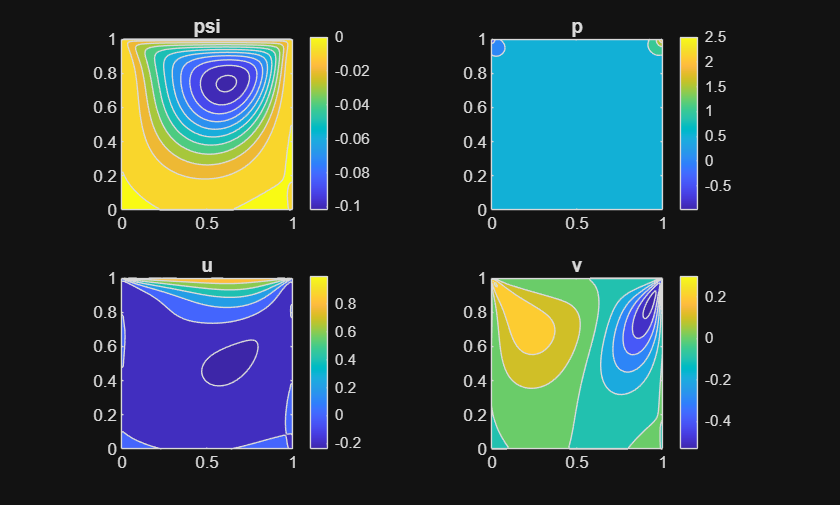

% Create test set using meshgrid.
numTestSamples = 100;
x = linspace(0, 1, numTestSamples)';
y = x;
[xt, yt] = meshgrid(x, y);

% Flatten gridpoints and prepare data.
xTest = dlarray(xt(:));
yTest = dlarray(yt(:));
if canUseGPU
    xTest = gpuArray(xTest);
    yTest = gpuArray(yTest);
end

% Evaluate the network.
[psiTest, pTest, uTest, vTest] = dlfeval(@calculateStreamfunctionPressureAndVelocity, net, xTest, yTest);

% Return predictions to grid and plot.
ut = unflattenAndExtract(uTest, numTestSamples);
vt = unflattenAndExtract(vTest, numTestSamples);
pt = unflattenAndExtract(pTest, numTestSamples);
psit = unflattenAndExtract(psiTest, numTestSamples);

figure; 
subplot(2,2,1)
contourf(xt, yt, psit)
colorbar
axis equal
title('psi')

subplot(2,2,2)
contourf(xt, yt, pt)
colorbar
axis equal
title('p')

subplot(2,2,3)
contourf(xt, yt, ut)
colorbar
axis equal
title('u')

subplot(2,2,4)
contourf(xt, yt, vt)
colorbar
axis equal
title('v')

## Loss function and helper functions

function [loss, grads, lossEqnX, lossEqnY, lossBC] = pinnsLossFunction(net, xyEquation, xyBoundary, zeroVector, uvBoundary, Re)

% Get model outputs at interior points.
xeq = xyEquation(:, 1);
yeq = xyEquation(:, 2);
[psi, p] = forward(net, xeq, yeq);

% Compute gradients.
psisum = sum(psi,1);
u = dlgradient(psisum, yeq, EnableHigherDerivatives=true);
v = -1.*dlgradient(psisum, xeq, EnableHigherDerivatives=true);

usum = sum(u,1);
ux = dlgradient(usum, xeq, EnableHigherDerivatives=true);
uy = dlgradient(usum, yeq, EnableHigherDerivatives=true);
uxx = dlgradient(sum(ux,1), xeq, EnableHigherDerivatives=true);
uyy = dlgradient(sum(uy,1), yeq, EnableHigherDerivatives=true);

vsum = sum(v,1);
vx = dlgradient(vsum, xeq, EnableHigherDerivatives=true);
vy = dlgradient(vsum, yeq, EnableHigherDerivatives=true);
vxx = dlgradient(sum(vx,1), xeq, EnableHigherDerivatives=true);
vyy = dlgradient(sum(vy,1), yeq, EnableHigherDerivatives=true);

psum = sum(p,1);
px = dlgradient(psum, xeq, EnableHigherDerivatives=true);
py = dlgradient(psum, yeq, EnableHigherDerivatives=true);

% Momentum equations.
lx = u.*ux + v.*uy + px - (1/Re).*(uxx + uyy);
ly = u.*vx + v.*vy + py - (1/Re).*(vxx + vyy);

% Combine for equation loss.
lossEqnX = logCoshLoss(lx, zeroVector);
lossEqnY = logCoshLoss(ly, zeroVector);

% Get model outputs at boundary points.
xbd = xyBoundary(:, 1);
ybd = xyBoundary(:, 2);
psibd = forward(net, xbd, ybd);

psibdsum = sum(psibd,1);
ubd = dlgradient(psibdsum, ybd, EnableHigherDerivatives=true);
vbd = -1.*dlgradient(psibdsum, xbd, EnableHigherDerivatives=true);

uvbd = cat(2, ubd, vbd);
lossBC = logCoshLoss(uvbd, uvBoundary);

% Total loss and model gradients
loss = lossEqnX + lossEqnY + lossBC;
grads = dlgradient(loss, net.Learnables);
end

function loss = logCoshLoss(y, t)
% log-cosh loss function
e = y - t;
loss = mean( log(cosh(e)), 'all' );
end

function [psi, p, u, v] = calculateStreamfunctionPressureAndVelocity(net, x, y)
% Compute the streamfunction psi, pressure p and velocity (u,v) given
% input positions (x,y).
[psi, p] = forward(net, x, y);
psisum = sum(psi,1);
u = dlgradient(psisum, y);
v = -1.*dlgradient(psisum, x);
end

function x = unflattenAndExtract(xflat, sz)
x = reshape(xflat, [sz sz]);
x = extractdata(x);
end